# ME 552 Midterm, Problem 3-9

Dominic Riccoboni

Date Created: 10/23/2021

Date Last Modified: 10/23/2021

clear all

## Problem 3-9 (continued)

### Original Problem

Consider the 2-D, steady-state rectangular region $0 \leq x \leq a, 0 \leq y \leq b$  in which internal energy is generated at a constant rate $g_0 [\frac{W}{m^3}]$ and subjected to the following boundary conditions: boundaries at $x = 0$ and $y = 0$ are kept insulated, whereas the boundaries at $x = a$ and $y = b$ are kept at zero temperature. Calculate the temperature distribution $T(x,y)$.

Parameter Specifications (where thermal conductivity is for aluminum at STP):


$$\[ \begin{array}{ll}

g_0 = 1.00 \times 10^6 ~[\frac{W}{m^3}] && a = 0.200 ~[m]\\

k = 240~ [\frac{W}{m*^{\circ}C}]  && b = 0.100 ~[m]


 \end{array}\] $$


### Fourier Coefficients

Verify that the Fourier coefficients after intregration are as follows:


$$C_n = \frac{2g_0(-1)^n}{ak\lambda_n^3cosh(\lambda_nb)}~for~n = 1,2,3... $$
 

where


$$\lambda_n = \frac{2n-1}{2a} ~for~n = 1,2,3...$$


Verification:

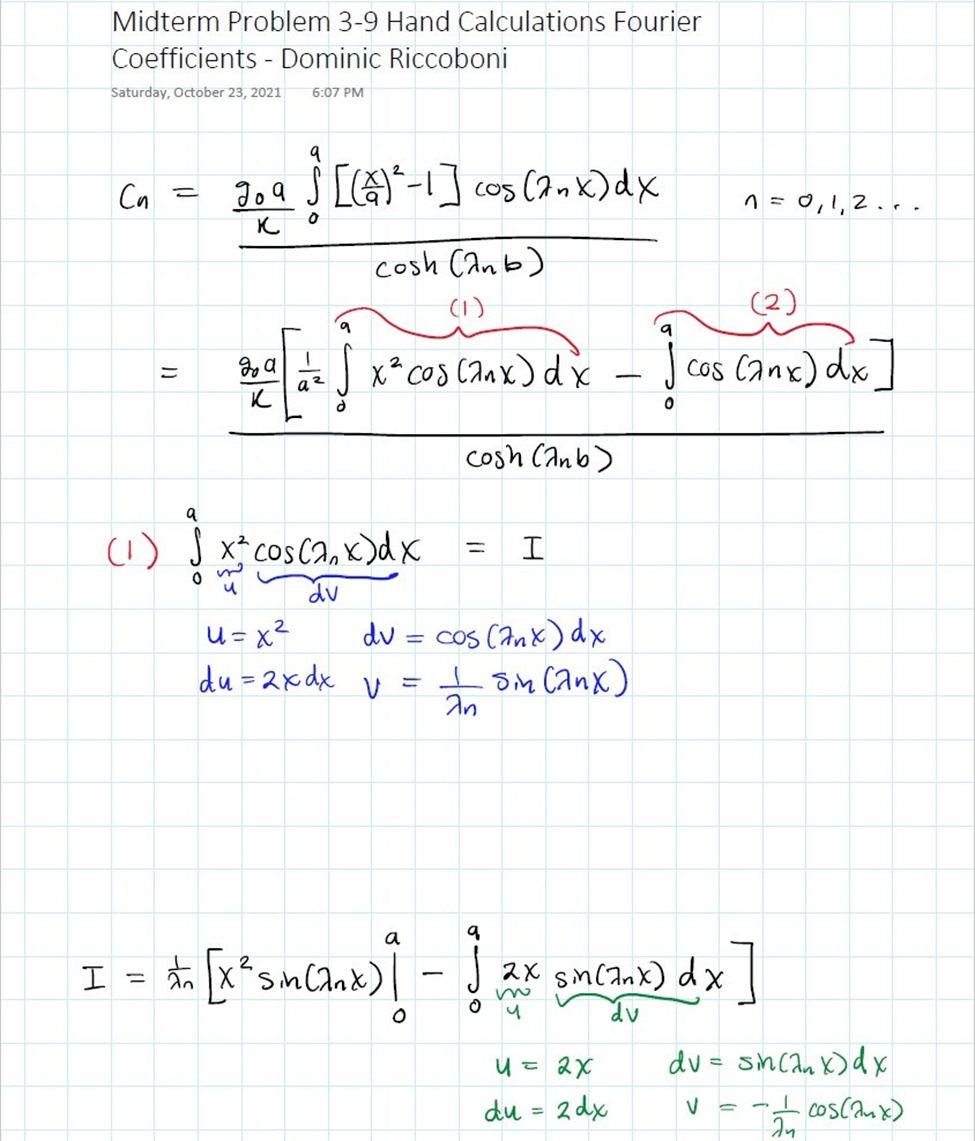

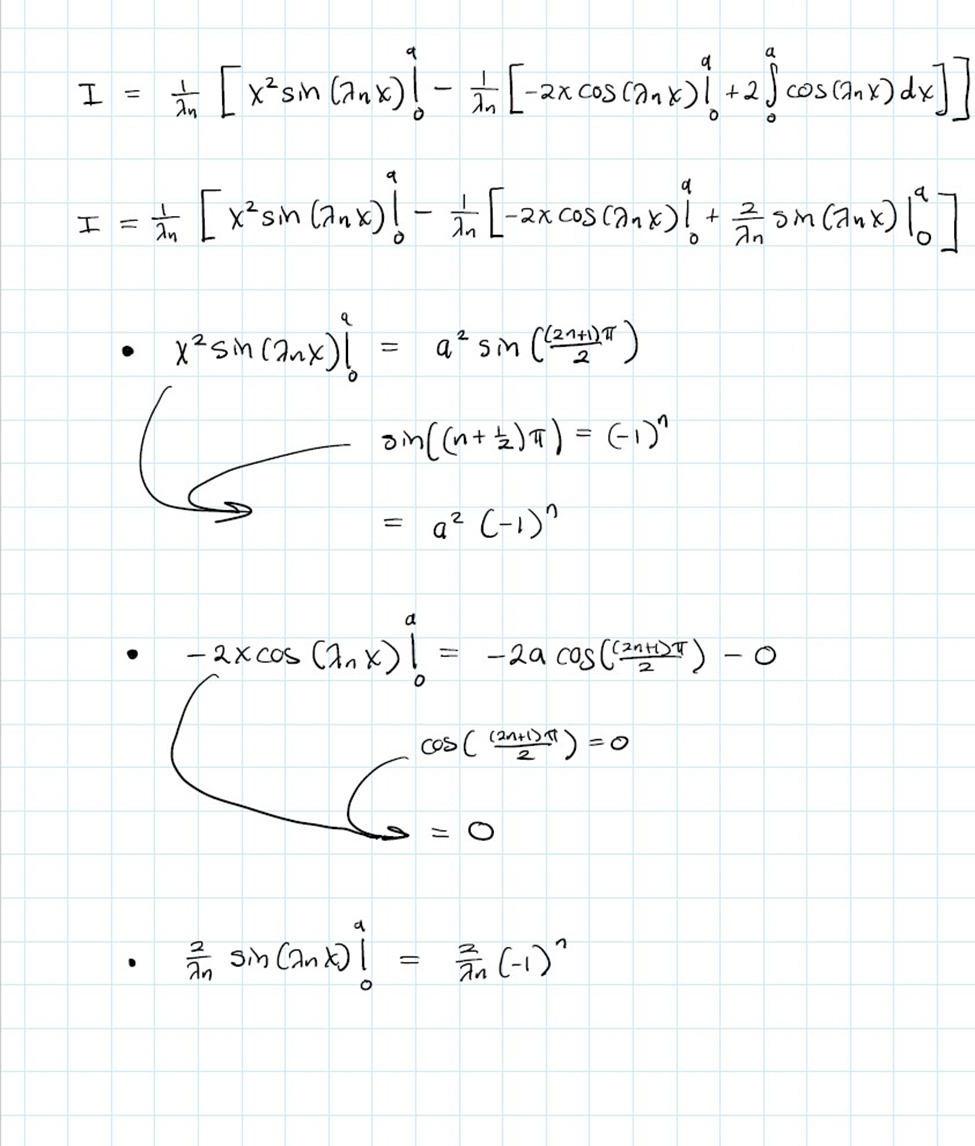

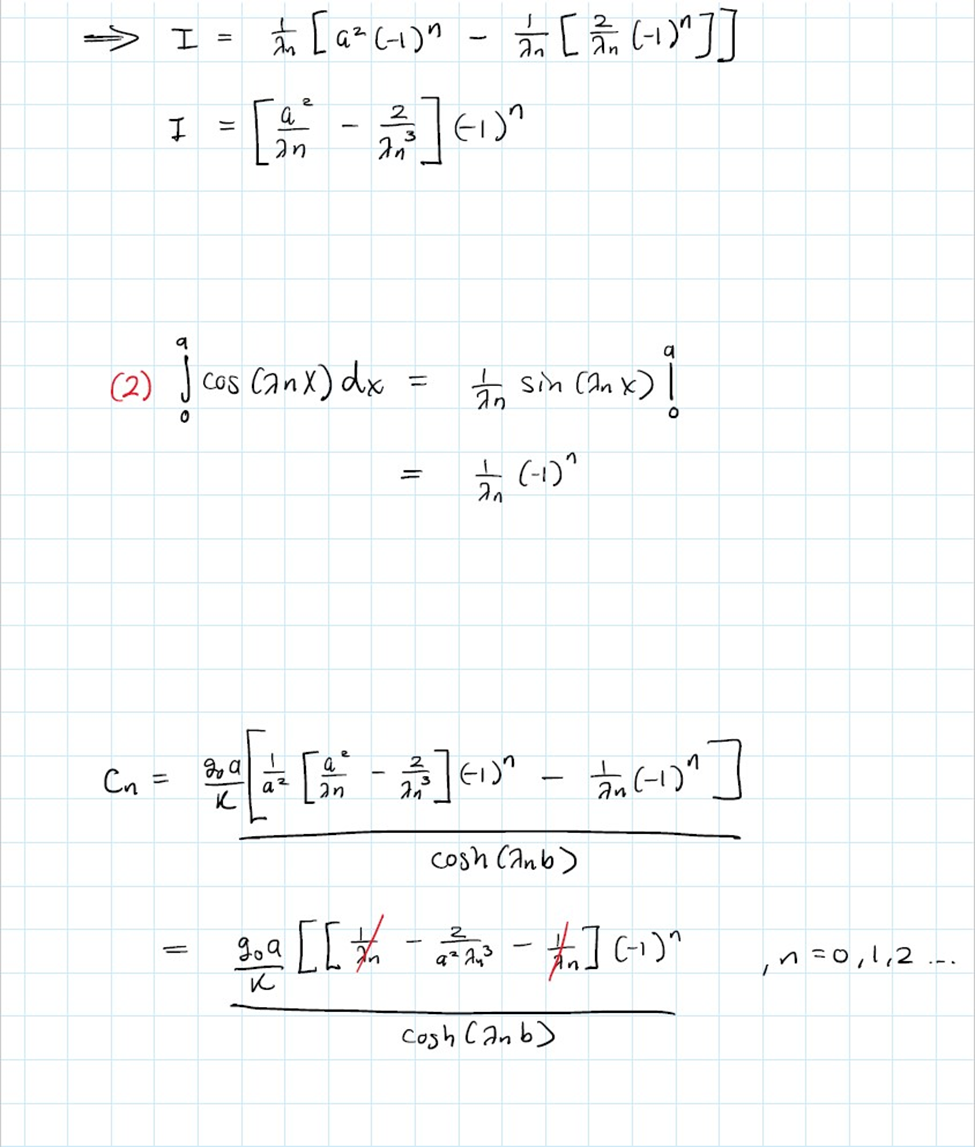

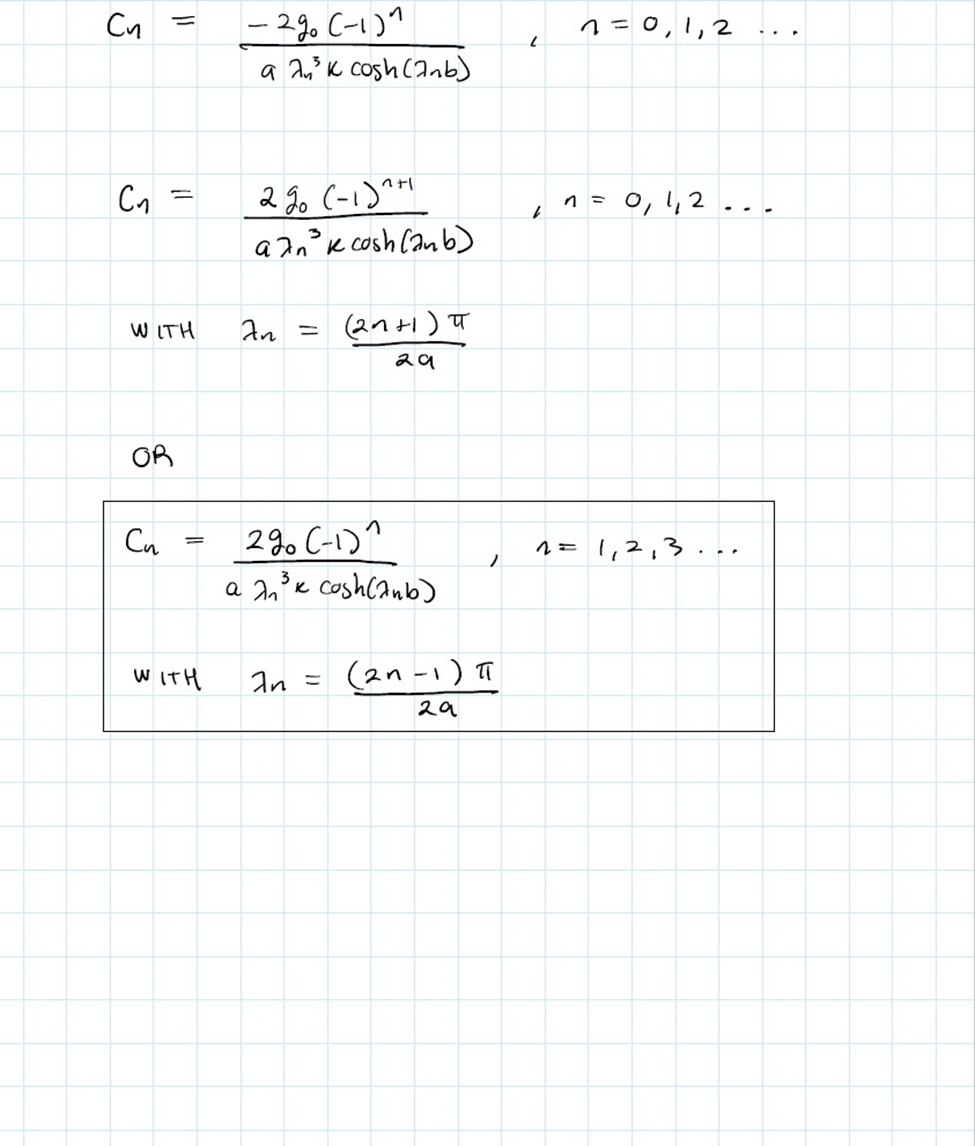

### Produce Solution Plots

The total solution, $T(x,y)$ is decomposed as follows:


$$T(x,y) = \Psi(x,y) + \Phi(x)$$


where


$$\Psi(x,y) = \sum_{n=1}^{\infty}C_ncos(\lambda_nx) cosh(\lambda_ny)$$


and


$$\Phi(x) = \frac{g_0a^2}{2k}[1 - (\frac{x}{a})^2] $$


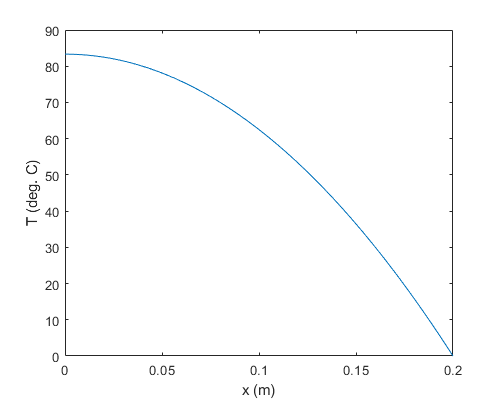

%System Parameters
g0 = 1e6; % [W/m^3], uniform inter heat generation
k = 240; % [W/(m*K)], thermal conductivity
a = 0.2; % [m], length in x-direction
b = 0.1; % [m], length in y-direction 

%Calculate Eigenvalues and Fourier Coefficients
n = 1:200; % Eignevalue index
lambda = (2*n-1)*pi/(2*a);
C = 2*g0*(-1).^n./(a*lambda.^3*k.*cosh(lambda*b));

%Allocate memory for solution's domain vectors
N = 101; %Number of data points for each dimension
x = linspace(0,a,N); %Break up the x dimension width into N data points
y = linspace(0,b,N); %Break up the y dimension width into N data points

%T(x,y) evaluated at the domain variables

phi = zeros(N,1); % Initialize 1-D ODE solution
T = zeros(N); % Initialize 2-D PDE solution
Tmax = g0*a^2/(2*k); % deg. C, Maximum T for 1-D ODE problem
for i = 1:N
phi(i) = Tmax*(1 - (x(i)/a)^2);
    for j = 1:N
        T(i,j) = phi(i) + ...
        sum(C.*cos(lambda*x(i)).*cosh(lambda*y(j)));
    end
end

%Produce Plots
%Plot 1-D ODE Solution
figure('Name','1-D ODE Solution','Position',[50 200 500 400])
plot(x,phi);
xlabel('x (m)') % Label x-axis
ylabel('T (deg. C)') % Label y-axis

Figure 1. 1-D ODE solution $\Phi(x)$

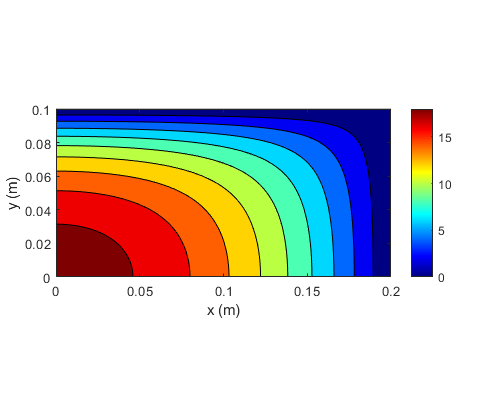

figure('Name','2-D PDE Solution','Position',[600 200 500 400])
contourf(x,y,T);
colormap jet; % Set colors used for contours
colorbar % Add a scale to the plot
axis([0 a 0 b]) % Set axis limits
xlabel('x (m)') % Label x-axis
ylabel('y (m)') % Label y-axis
axis equal tight % Make x and y axes to scale

Figure 2. 2-D PDE solution $T(x,y)$

### Verify How Many Terms in the Solution are Needed to Get and Accurate Result

The top right corner, $T(a,b)$, and the center of the plate, $T(\frac{a}{2}, \frac{b}{2}) $, are chosen locations to calculate the percent error in the solution. Plots of percent error vs the number of Fourier coefficients are generated and discussed. 

M = 20; % Maximum number of summation terms

%First, choose top-right corner as the location to compute errors
i = N 

i = 101

j = N 

j = 101


% 1-D ODE solution at top right corner
phi = Tmax*(1 - (x(i)/a)^2); 

% Initialize percent error vector for the top right corner
error1 = zeros(M-1,1); 

%Reference temperature for error calculation in the center of the plate. This is the value
%computed for the first 200 coefficients in the Fourier series.
T_ref_1 = T(i,j);

fprintf('Percent Error at: x = %4.2f m, y = %4.2f m:\n',x(i),y(i));

Percent Error at: x = 0.20 m, y = 0.10 m:


for m = 1:M
    Txy = phi + ...
    sum(C(1:m).*cos(lambda(1:m)*x(i)).*cosh(lambda(1:m)*y(j)));
    error1(m) = 100*(T_ref_1-Txy)/T_ref_1;
    fprintf('%10.2e \n',error1(m));
end

  2.47e+01 
  1.63e+01 
  4.60e+00 
  3.07e+00 
  5.13e+00 
  2.87e+00 
  3.42e+00 
  2.44e+00 
  2.62e+00 
  2.09e+00 
  2.16e+00 
  1.84e+00 
  1.86e+00 
  1.64e+00 
  1.64e+00 
  1.49e+00 
  1.24e+00 
  1.13e+00 
  1.11e+00 
  1.03e+00 



%Second, choose the center as the location to compute errors
i =round(N/2)

i = 51

j =round(N/2) 

j = 51


% 1-D ODE solution at top right corner
phi = Tmax*(1 - (x(i)/a)^2); 

% Initialize percent error vector for the top right corner
error2 = zeros(M-1,1); 

%Reference temperature for error calculation in the center of the plate. This is the value
%computed for the first 200 coefficients in the Fourier series.
T_ref_2 = T(i,j);

fprintf('Percent Error at: x = %4.2f m, y = %4.2f m:\n',x(i),y(i));

Percent Error at: x = 0.10 m, y = 0.05 m:


for m = 1:M
    Txy = phi + ...
    sum(C(1:m).*cos(lambda(1:m)*x(i)).*cosh(lambda(1:m)*y(j)));
    error2(m) = 100*(T_ref_2-Txy)/T_ref_2;
    fprintf('%10.2e \n',error2(m));
end

 -5.47e+00 
  6.34e-01 
  6.93e-02 
 -2.31e-02 
 -3.32e-03 
  1.61e-03 
  2.53e-04 
 -1.51e-04 
 -2.46e-05 
  1.67e-05 
  2.78e-06 
 -2.07e-06 
 -3.47e-07 
  2.76e-07 
  4.66e-08 
 -3.89e-08 
 -6.61e-09 
  5.74e-09 
  9.78e-10 
 -8.78e-10 


Plot the percent error at each location as a function fo the number of terms 

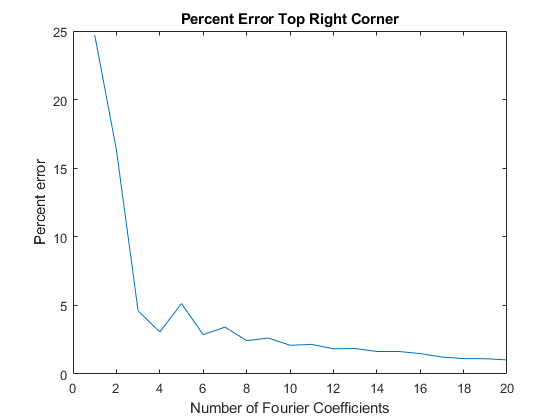

figure
plot(1:M,error1)
xlabel('Number of Fourier Coefficients')
ylabel('Percent error')
title('Percent Error Top Right Corner')

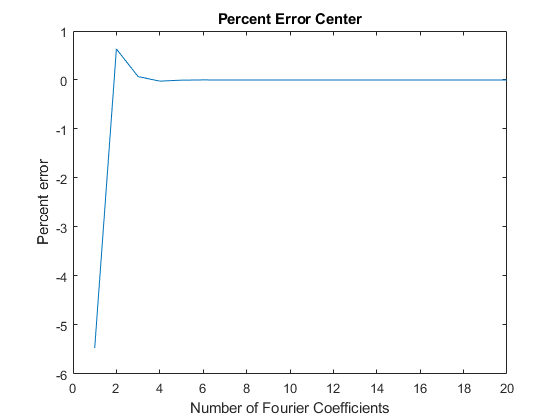


figure
plot(1:M,error2)
xlabel('Number of Fourier Coefficients')
ylabel('Percent error')
title('Percent Error Center')

### Discussion

It is clear from the percent error plots that the solution at the center converges much faster than the solution at the top right corner of the plate. Typically, an uncertainty of $\pm1^{\circ}C$ is acceptable for engineering applications. For both cases, the first term in the Fourier expansion is within this tolerance.


fprintf('T(a,b) is off by %e degrees celcius at the first Fourier coefficient.', error1(1)/100*T_ref_1)

T(a,b) is off by -1.728760e-15 degrees celcius at the first Fourier coefficient.

fprintf('T(a/2,b/2) is off by %e degrees celcius at the first Fourier coefficient.', error2(1)/100*T_ref_2)

T(a/2,b/2) is off by -6.742317e-01 degrees celcius at the first Fourier coefficient.

The solution $T(x,y)$ appears correct. The boundary at $x = a$ and $y = b$